# This is the live script for ESE 6190 HW5 MPC Theory II Exercise 1

clear all
clc
%% Basic Deifinition, run this block first
% Define system matrixcs:
A = [1.2, 1; 0, 1];
% Define input matrixcs:
B = [0; 1];
% Define weight matrices:
Q = eye(2);
R = 1;
% Define the box constraints for state and input
n = size(A, 1);
m = size(B, 2);
umin = -1*ones(m,1);
umax = 1*ones(m,1);
xmin = -15*ones(n,1);
xmax = 15*ones(n,1);

## Ex 1.1-1.3 Approach 1

% Define terminal set X_N = 0
Af = [eye(n); -eye(n)];
bf = [zeros(n,1); zeros(n,1)];

% Define terminal weight P, since the terminal set is X_N = 0
% as long as the cost is positive definite and initial feasibility exist
P_N = Q;

% initial state:
x0 = [2; -1];
% Simulaion time
T_sim = 25;
% Horizon Length
N = 3;

## 1.2 For N=3, compare the open loop and closed-loop

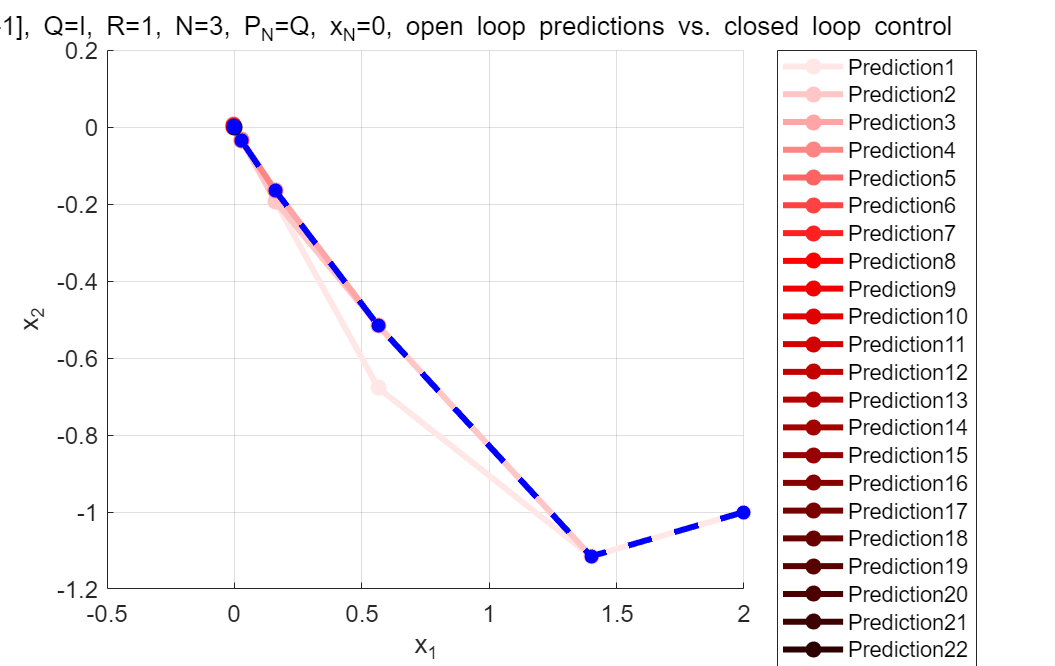

% record for the plot
U_record = zeros(T_sim*m,1);
X_record = zeros(T_sim*n,1);
% record the prediction input and state over whole open loop horizon
U_pre_record = zeros(T_sim*m,N); % each m row represent the whole open-loop prediction horizon instead of just the first one
X_pre_record = zeros(T_sim*m,N); % each n row represent the whole open-loop prediction horizon instead of just the first one

for i = 1 : T_sim
    if i == 1
        x = x0;
    end
    [u,U] = mympc(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,Af,bf,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U_record((i-1)*m+1:i*m,1) = u;
    X_record((i-1)*n+1:i*n,1) = xp;
    x = xp;

    % open loop prediction for U and X
    U_pre_record((i-1)*m+1:i*m,1) = U(1:m);
    X_pre_record((i-1)*n+1:i*n,1) = xp;
    for j = 2:N
        u_pre = U((j-1)*m+1:j*m);
        x_pre = system_sim(xp,u_pre,A,B);
        U_pre_record((i-1)*m+1:i*m,j) = u_pre;
        X_pre_record((i-1)*n+1:i*n,j) = x_pre;
        xp = x_pre;
    end
end
X_record = [x0;X_record];
X_pre_record = [X_record(1:n*T_sim), X_pre_record];

% plot the closed-loop result and 25 open loop predictions for this system
f=figure;
f.Position = [100 100 950 600];
hold on
grid on
labels={};
for i = 1 : T_sim
    color = [255-(i>8)*(i-8)*15,(264-i*33)*(i<=8),(264-i*33)*(i<=8)]/255; % hacks for coloring
    plot(X_pre_record((i-1)*n+1,:),X_pre_record((i-1)*n+2,:),'-o','LineWidth',3,'Color', color,'MarkerSize',5,'MarkerFaceColor',color)
    labels{i}=['Prediction',num2str(i)];
end
plot(X_record(1:n:end),X_record(2:n:end),'--o','LineWidth',3,'Color','b','MarkerFaceColor','b','MarkerSize',4)
labels{end+1}='Closed-Loop';
title('x_0 = [2;-1], Q=I, R=1, N=3, P_N=Q, x_N=0, open loop predictions vs. closed loop control')
ylabel('x_2')
xlabel('x_1')
set(gca,'FontSize',12);
legend(labels,'Location','eastoutside')

## 1.3 For N=10, compare the open loop and closed-loop

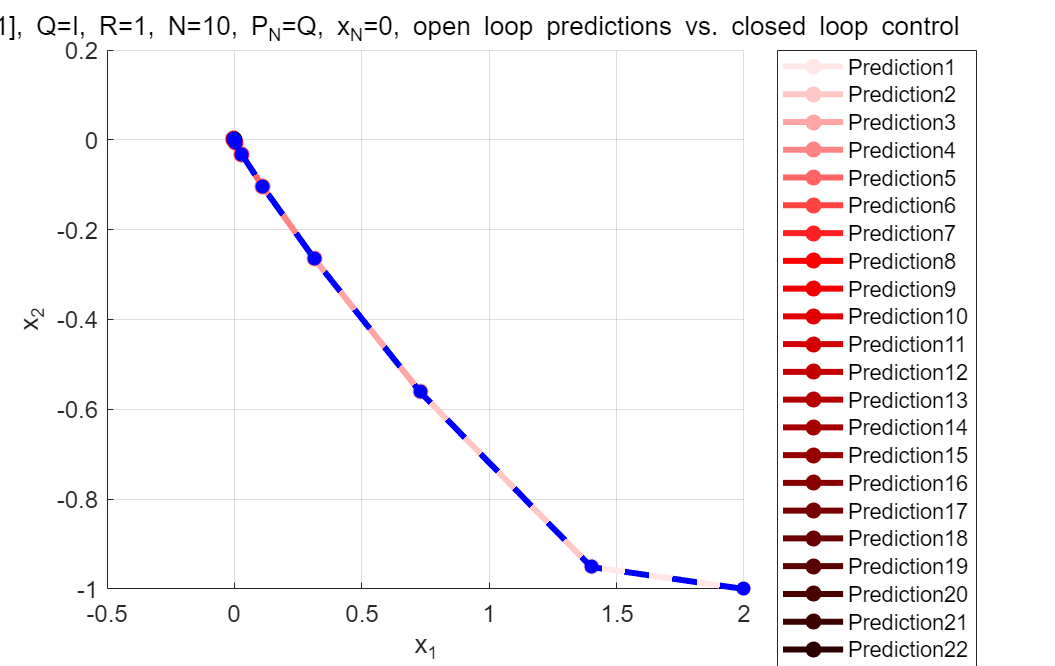

% Horizon Length
N = 10;
% record for the plot
U_record = zeros(T_sim*m,1);
X_record = zeros(T_sim*n,1);
% record the prediction input and state over whole open loop horizon
U_pre_record = zeros(T_sim*m,N); % each m row represent the whole open-loop prediction horizon instead of just the first one
X_pre_record = zeros(T_sim*m,N); % each n row represent the whole open-loop prediction horizon instead of just the first one

for i = 1 : T_sim
    if i == 1
        x = x0;
    end
    [u,U] = mympc(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,Af,bf,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U_record((i-1)*m+1:i*m,1) = u;
    X_record((i-1)*n+1:i*n,1) = xp;
    x = xp;

    % open loop prediction for U and X
    U_pre_record((i-1)*m+1:i*m,1) = U(1:m);
    X_pre_record((i-1)*n+1:i*n,1) = xp;
    for j = 2:N
        u_pre = U((j-1)*m+1:j*m);
        x_pre = system_sim(xp,u_pre,A,B);
        U_pre_record((i-1)*m+1:i*m,j) = u_pre;
        X_pre_record((i-1)*n+1:i*n,j) = x_pre;
        xp = x_pre;
    end
end
X_record = [x0;X_record];
X_pre_record = [X_record(1:n*T_sim), X_pre_record];

% plot the closed-loop result and 25 open loop predictions for this system
f=figure;
f.Position = [100 100 950 600];
hold on
grid on
labels={};
for i = 1 : T_sim
    color = [255-(i>8)*(i-8)*15,(264-i*33)*(i<=8),(264-i*33)*(i<=8)]/255; % hacks for coloring
    plot(X_pre_record((i-1)*n+1,:),X_pre_record((i-1)*n+2,:),'-o','LineWidth',3,'Color', color,'MarkerSize',5,'MarkerFaceColor',color)
    labels{i}=['Prediction',num2str(i)];
end
plot(X_record(1:n:end),X_record(2:n:end),'--o','LineWidth',3,'Color','b','MarkerFaceColor','b','MarkerSize',4)
labels{end+1}='Closed-Loop';
title('x_0 = [2;-1], Q=I, R=1, N=10, P_N=Q, x_N=0, open loop predictions vs. closed loop control')
ylabel('x_2')
xlabel('x_1')
set(gca,'FontSize',12);
legend(labels,'Location','eastoutside')

## Ex 1.4-1.5 Approach 2

% As problem decribed, get the LQR solution, cost as terminal cost, gain to
% form closed loop LTI
[K,P_N,~] = dlqr(A,B,Q,R,0);
F_inf = -K;
Acl = A + B*(F_inf);

## 1.4 Get the terminal set with the help of MPT toolbox

% MPT Toolbox to calculate the maximal invariant set
system = LTISystem('A',Acl);
Xtilde = Polyhedron('A',[eye(2);-eye(2);F_inf;-F_inf],'b',[15;15;15;15;1;1]);
Oinf = system.invariantSet('X',Xtilde);

Iteration 1...
Iteration 2...


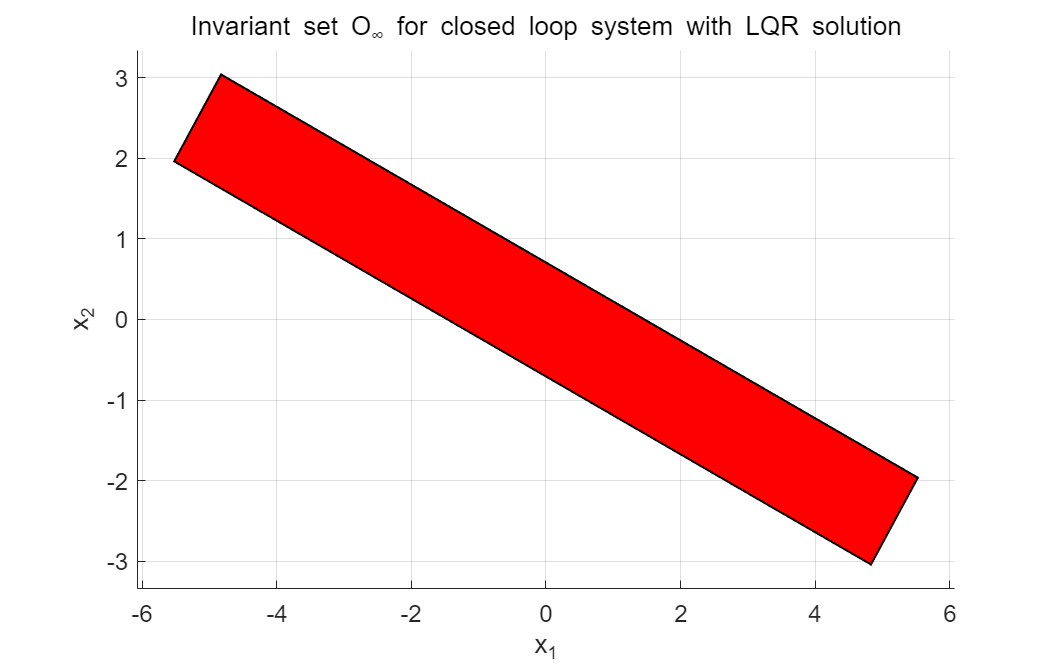

f=figure;
f.Position = [100 100 950 600];
plot(Oinf)
ylabel('x_2')
xlabel('x_1')
set(gca,'FontSize',12);
title('Invariant set O_∞ for closed loop system with LQR solution')


% Define terminal set X_N = X_f given by invariant set of closed-loop system
Af = Oinf.A;
bf = Oinf.b;


## 1.5 For N=3, compare the open loop and closed-loop

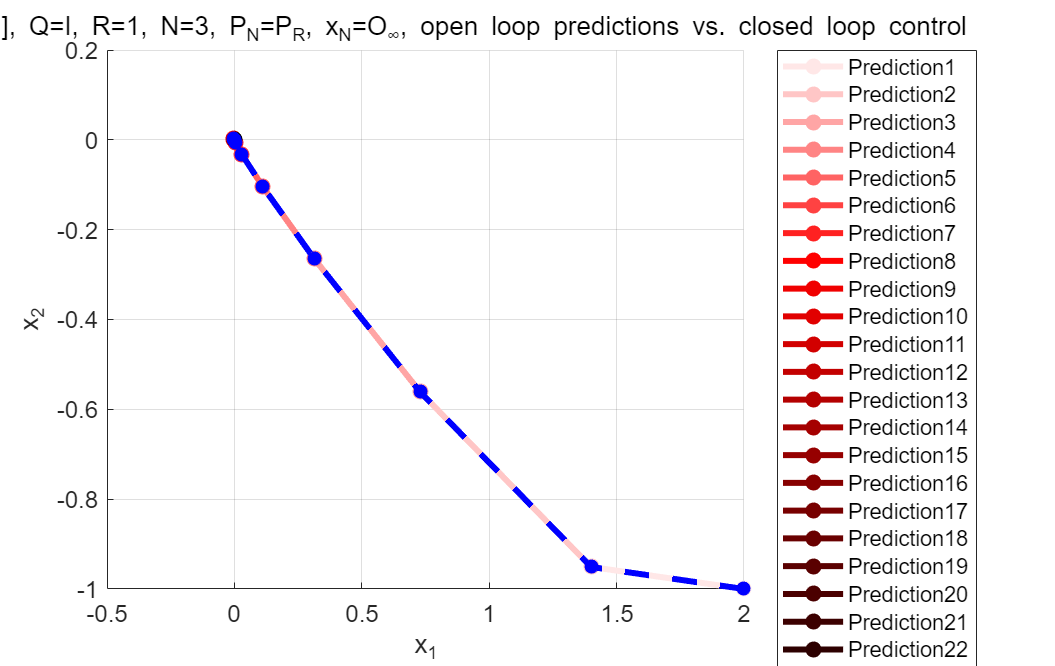

% initial state:
x0 = [2; -1];
% Simulaion time
T_sim = 25;
% Horizon Length
N = 3;
% record for the plot
U_record = zeros(T_sim*m,1);
X_record = zeros(T_sim*n,1);
% record the prediction input and state over whole open loop horizon
U_pre_record = zeros(T_sim*m,N); % each m row represent the whole open-loop prediction horizon instead of just the first one
X_pre_record = zeros(T_sim*m,N); % each n row represent the whole open-loop prediction horizon instead of just the first one

for i = 1 : T_sim
    if i == 1
        x = x0;
    end
    [u,U] = mympc(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,Af,bf,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U_record((i-1)*m+1:i*m,1) = u;
    X_record((i-1)*n+1:i*n,1) = xp;
    x = xp;

    % open loop prediction for U and X
    U_pre_record((i-1)*m+1:i*m,1) = U(1:m);
    X_pre_record((i-1)*n+1:i*n,1) = xp;
    for j = 2:N
        u_pre = U((j-1)*m+1:j*m);
        x_pre = system_sim(xp,u_pre,A,B);
        U_pre_record((i-1)*m+1:i*m,j) = u_pre;
        X_pre_record((i-1)*n+1:i*n,j) = x_pre;
        xp = x_pre;
    end
end
X_record = [x0;X_record];
X_pre_record = [X_record(1:n*T_sim), X_pre_record];

% plot the closed-loop result and 25 open loop predictions for this system
f=figure;
f.Position = [100 100 950 600];
hold on
grid on
labels={};
for i = 1 : T_sim
    color = [255-(i>8)*(i-8)*15,(264-i*33)*(i<=8),(264-i*33)*(i<=8)]/255; % hacks for coloring
    plot(X_pre_record((i-1)*n+1,:),X_pre_record((i-1)*n+2,:),'-o','LineWidth',3,'Color', color,'MarkerSize',5,'MarkerFaceColor',color)
    labels{i}=['Prediction',num2str(i)];
end
plot(X_record(1:n:end),X_record(2:n:end),'--o','LineWidth',3,'Color','b','MarkerFaceColor','b','MarkerSize',4)
labels{end+1}='Closed-Loop';
title('x_0 = [2;-1], Q=I, R=1, N=3, P_N=P_R, x_N=O_∞, open loop predictions vs. closed loop control')
ylabel('x_2')
xlabel('x_1')
set(gca,'FontSize',12);
legend(labels,'Location','eastoutside')

## Ex 1.6-1.7 Approach 3

% As problem decribed, use the stablizing control gain and solve the
% lyapunov equation to get the terminal cost
K = [1.595, 2.35];
Acl = A + B*(-K);
P_N = dlyap(Acl,Q+K'*R*K);
system = LTISystem('A',Acl);
Xtilde = Polyhedron('A',[eye(2);-eye(2);-K;K],'b',[15;15;15;15;1;1]);
Oinf = system.invariantSet('X',Xtilde);

Iteration 1...
Iteration 2...


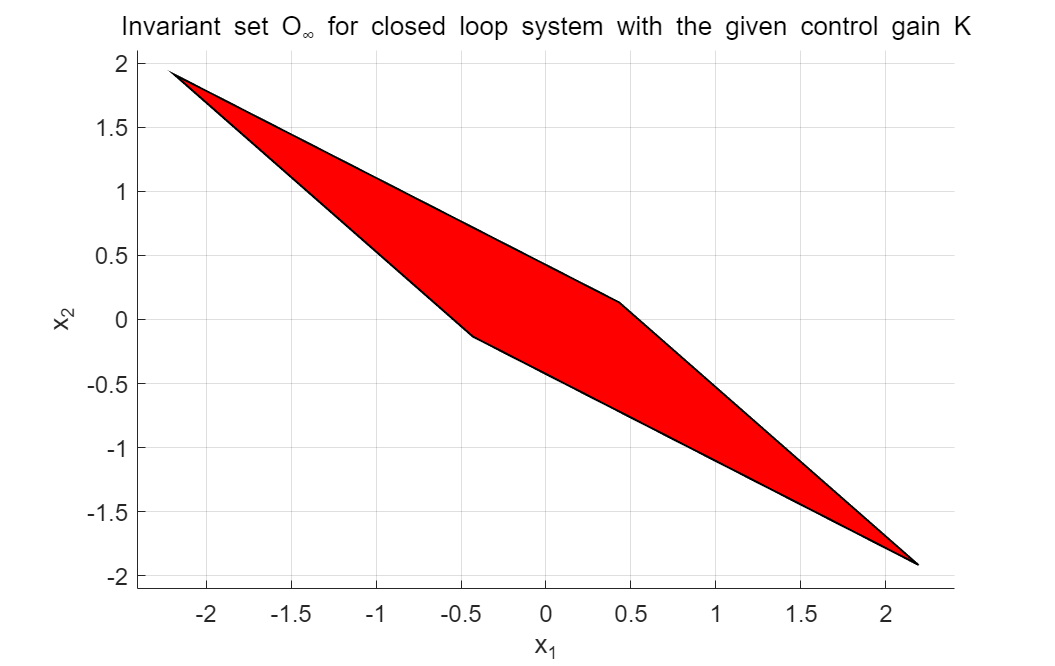

f=figure;
f.Position = [100 100 950 600];
plot(Oinf)
ylabel('x_2')
xlabel('x_1')
set(gca,'FontSize',12);
title('Invariant set O_∞ for closed loop system with the given control gain K')

## 1.7 For N=3, compare the open loop and closed-loop

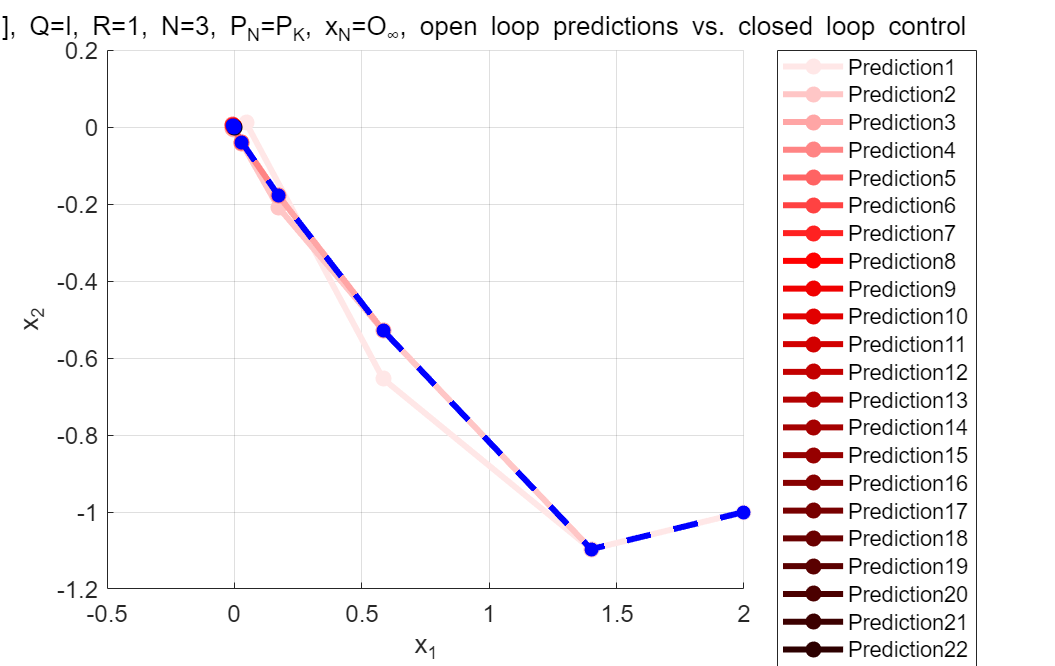

% initial state:
x0 = [2; -1];
% Simulaion time
T_sim = 25;
% Horizon Length
N = 3;
% record for the plot
U_record = zeros(T_sim*m,1);
X_record = zeros(T_sim*n,1);
% record the prediction input and state over whole open loop horizon
U_pre_record = zeros(T_sim*m,N); % each m row represent the whole open-loop prediction horizon instead of just the first one
X_pre_record = zeros(T_sim*m,N); % each n row represent the whole open-loop prediction horizon instead of just the first one

for i = 1 : T_sim
    if i == 1
        x = x0;
    end
    [u,U] = mympc(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,Af,bf,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U_record((i-1)*m+1:i*m,1) = u;
    X_record((i-1)*n+1:i*n,1) = xp;
    x = xp;

    % open loop prediction for U and X
    U_pre_record((i-1)*m+1:i*m,1) = U(1:m);
    X_pre_record((i-1)*n+1:i*n,1) = xp;
    for j = 2:N
        u_pre = U((j-1)*m+1:j*m);
        x_pre = system_sim(xp,u_pre,A,B);
        U_pre_record((i-1)*m+1:i*m,j) = u_pre;
        X_pre_record((i-1)*n+1:i*n,j) = x_pre;
        xp = x_pre;
    end
end
X_record = [x0;X_record];
X_pre_record = [X_record(1:n*T_sim), X_pre_record];

% plot the closed-loop result and 25 open loop predictions for this system
f=figure;
f.Position = [100 100 950 600];
hold on
grid on
labels={};
for i = 1 : T_sim
    color = [255-(i>8)*(i-8)*15,(264-i*33)*(i<=8),(264-i*33)*(i<=8)]/255; % hacks for coloring
    plot(X_pre_record((i-1)*n+1,:),X_pre_record((i-1)*n+2,:),'-o','LineWidth',3,'Color', color,'MarkerSize',5,'MarkerFaceColor',color)
    labels{i}=['Prediction',num2str(i)];
end
plot(X_record(1:n:end),X_record(2:n:end),'--o','LineWidth',3,'Color','b','MarkerFaceColor','b','MarkerSize',4)
labels{end+1}='Closed-Loop';
title('x_0 = [2;-1], Q=I, R=1, N=3, P_N=P_K, x_N=O_∞, open loop predictions vs. closed loop control')
ylabel('x_2')
xlabel('x_1')
set(gca,'FontSize',12);
legend(labels,'Location','eastoutside')

## Ex 1.8-1.9 Persistent Feasibility

## 1.8 plot control invariant set

% Maximal Control Invariant set, from theory, should be calculated by the
% algorithm taught in the lecture, i.e. intersection, compute preset and 
% test equality, but here we can use the MPT toolbox to quickly get it
% computes a control invariant set for LTI system x^+ = A*x+B*u
system = LTISystem('A', A, 'B', B);
system.x.min = [-15; -15];
system.x.max = [15; 15];
system.u.min = -1;
system.u.max = 1;
C_inf = system.invariantSet()

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...
Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities  24 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


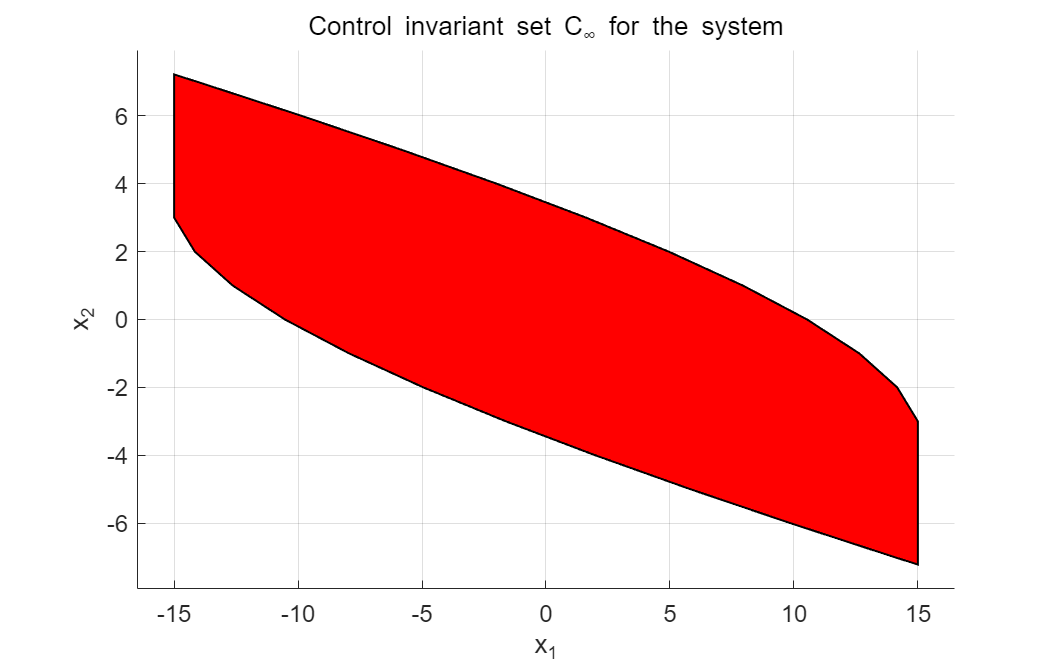

f=figure;
f.Position = [100 100 950 600];
plot(C_inf)
ylabel('x_2')
xlabel('x_1')
set(gca,'FontSize',12);
title('Control invariant set C_∞ for the system')

## 1.9  For N=1, compare the open loop and closed-loop

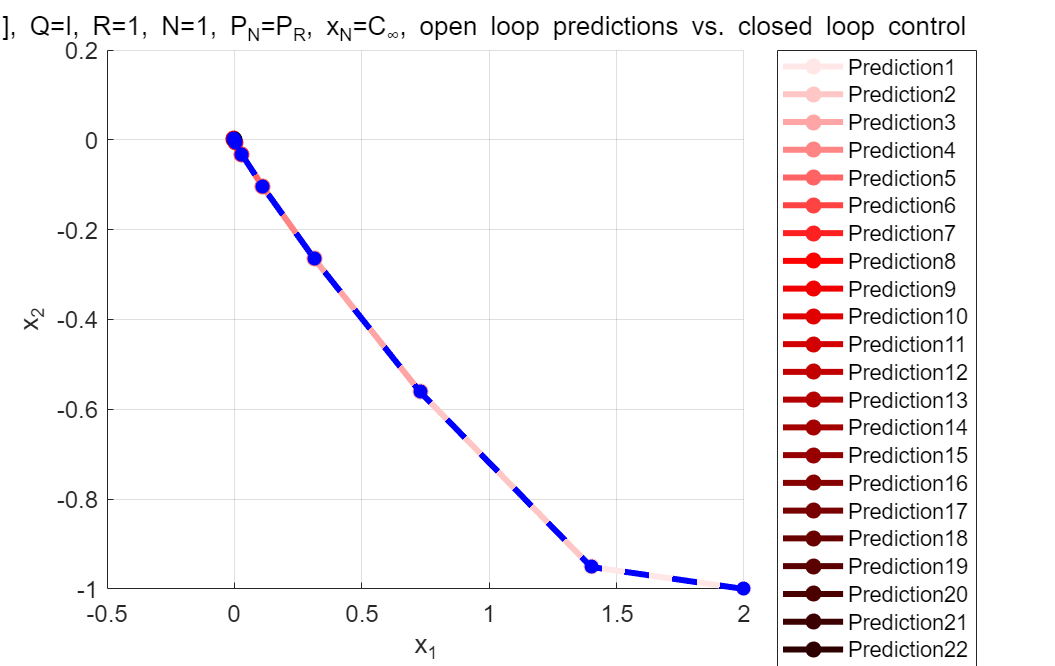

% Define terminal set X_N = X_f given by maximal control invariant set of the system
Af = C_inf.A;
bf = C_inf.b;
% As problem decribed, get the LQR solution, cost as terminal cost
[~,P_N,~] = dlqr(A,B,Q,R,0);
% initial state:
x0 = [2; -1];
% Simulaion time
T_sim = 25;
% Horizon Length
N = 1;
% record for the plot
U_record = zeros(T_sim*m,1);
X_record = zeros(T_sim*n,1);
% record the prediction input and state over whole open loop horizon
U_pre_record = zeros(T_sim*m,N); % each m row represent the whole open-loop prediction horizon instead of just the first one
X_pre_record = zeros(T_sim*m,N); % each n row represent the whole open-loop prediction horizon instead of just the first one

for i = 1 : T_sim
    if i == 1
        x = x0;
    end
    [u,U] = mympc(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,Af,bf,x);
    if isnan(u)
        disp(['At step ',num2str(i),' no control input found, problem infeasible'])
        break
    end
    xp = system_sim(x,u,A,B);
    U_record((i-1)*m+1:i*m,1) = u;
    X_record((i-1)*n+1:i*n,1) = xp;
    x = xp;

    % open loop prediction for U and X
    U_pre_record((i-1)*m+1:i*m,1) = U(1:m);
    X_pre_record((i-1)*n+1:i*n,1) = xp;
    for j = 2:N
        u_pre = U((j-1)*m+1:j*m);
        x_pre = system_sim(xp,u_pre,A,B);
        U_pre_record((i-1)*m+1:i*m,j) = u_pre;
        X_pre_record((i-1)*n+1:i*n,j) = x_pre;
        xp = x_pre;
    end
end
X_record = [x0;X_record];
X_pre_record = [X_record(1:n*T_sim), X_pre_record];

% plot the closed-loop result and 25 open loop predictions for this system
f=figure;
f.Position = [100 100 950 600];
hold on
grid on
labels={};
for i = 1 : T_sim
    color = [255-(i>8)*(i-8)*15,(264-i*33)*(i<=8),(264-i*33)*(i<=8)]/255; % hacks for coloring
    plot(X_pre_record((i-1)*n+1,:),X_pre_record((i-1)*n+2,:),'-o','LineWidth',3,'Color', color,'MarkerSize',5,'MarkerFaceColor',color)
    labels{i}=['Prediction',num2str(i)];
end
plot(X_record(1:n:end),X_record(2:n:end),'--o','LineWidth',3,'Color','b','MarkerFaceColor','b','MarkerSize',4)
labels{end+1}='Closed-Loop';
title('x_0 = [2;-1], Q=I, R=1, N=1, P_N=P_R, x_N=C_∞, open loop predictions vs. closed loop control')
ylabel('x_2')
xlabel('x_1')
set(gca,'FontSize',12);
legend(labels,'Location','eastoutside')

function [u,U] = mympc(A,B,Q,R,P,N,umin,umax,xmin,xmax,Af,bf,x)
%% This is the function used to solve the linear mpc problem
    %% linear quadratic optimal control via recursive approach
    %% The method is batch-approach based with substitution, i.e. shooting
    %% essentially, it is solving multiparametric QP about initial state x
    %% input:
    %  A: system matrix; B: Input matrix; N: control horizon;
    %  Q,R: weight matrices for states and inputs, respectively;
    %  P: terminal cost weight matrix;
    %  umin,umax: box constraints for control inputs, vectors
    %  xmin,xmax: box constraints for state inputs, vectors
    %  Af, bf: Terminal state constraint (convex polytope region)
    %  x: the current state (or say, the initial state for every mpc planning)
    %% output:
    %  u: the mpc control sequence u = [u0; u1; ...; uN-1];

    % first, rollout the dynamics to get Sx(mathcalA) and Su(mathcalB):
    n = size(A, 1);
    m = size(B, 2);
    Sx = zeros((N+1)*n, n);
    Su = zeros((N+1)*n, N*m);
    for i = 0:N
        Sx(i*n+1:(i+1)*n, 1:n) = A^i;
        for j = 0:N-1
            Su(i*n+1:(i+1)*n, j*m+1:(j+1)*m) = (i-j-1>=0)*A^(i-j-1)*B;
        end
    end

    % Then, get the stack-up weight matrices and rearrage as quadratic form
    % Q_bar(mathcal Q) and R_bar(mathcal R)
    I_N = eye(N);
    Q_bar = kron(I_N, Q);
    Q_bar(end+1:end+n, end+1:end+n) = P;
    R_bar = kron(I_N, R);
    H = 2*(Su'*Q_bar*Su + R_bar);
    F = 2*Sx'*Q_bar*Su;
    Y = x'*Sx'*Q_bar*Sx*x;
    
    % add state and input constraints, write them in inequality form
    % here write input constraints also in the stack-up inequality
    % infact, can use quadprog's lb and ub to set the input constraints 
    % since decision variable is u
    % x in (xmin, xmax), u in (umin, umax), xf in (xmin, xmax)
    Ax = [eye(n); -eye(n)];
    Au = [eye(m); -eye(m)];

    % constrauct G block by block
    G_u_block = kron(I_N,Au);
    % here 2 because we have 2 states and need to set upper and lower limit for each state
    % for more general case, consider using num_con_x = size(Ax,1)/n
    % i.e. num_con_x = 2 here
    G_x_block = zeros(N*n*2, N*m);
    for i = 0:N-1
        for j = 0:N-1
            G_x_block(i*2*n+1:(i+1)*2*n, j*m+1:(j+1)*m) = (i-j-1>=0)*Ax*A^(i-j-1)*B;
        end
    end

    % num_terminal_constraint = size(Af,1)/n
    num_tc = size(Af,1)/n;
    G_xf_block = zeros(n*num_tc, N*m);
    for j = 0:N-1
        G_xf_block(:, j*m+1:(j+1)*m) = (N-j-1>=0)*Af*A^(N-j-1)*B;
    end
    G = [G_u_block; G_x_block; G_xf_block];

    % construct E block by block
    E_u_block = zeros(N*2, n);
    E_x_block = zeros(N*n*2, n);
    for i = 0:N-1
        E_x_block(i*n*2+1:(i+1)*n*2, 1:n) = -Ax*A^i;
    end
    E_xf_block = -Af*A^N;
    E = [E_u_block;E_x_block;E_xf_block];

    % construct w block by block
    bu = [umax;-umin];
    bx = [xmax;-xmin];
    w_u_block = kron(ones(N,1),bu);
    w_x_block = kron(ones(N,1),bx);
    w = [w_u_block;w_x_block;bf];

    % Get the MPC control input from solving the QP
    options = optimoptions('quadprog','Display','off');
    U = quadprog((H+H')/2, F'*x, G, w+E*x,[],[],[],[],[],options);

    % return the first step:
    if isempty(U)
        u = nan;
    else
        u = U(1:m);
    end
end

function xp = system_sim(xk, uk, A, B)
    %% This is the function used to simulate single-step dynamics of the system
    %% input:
    %  A: system matrix; B: Input matrix; D: Disturbance matrix;
    %  xk: current state, uk: current input
    xp = A*xk + B*uk;
end
